# **HomeWork n°1 2022/23**

### ***Del Prete Rocco 0124002592***

### **PUNTO 1:**

**Definite la function Matlab che implementa la vostra funzione di riferimento e che chiamerete **`funrif.`


$$e^{-0.5x} \cdot \left(sin\left(\frac{p \cdot x}{2}\right)\right)^2+\frac {q}{1+x^2}cos(\pi x)-2$$


al posto di *p* e *q* inserisco rispettivamente il numero dei caratteri del nome e del cognome, calcolabili con la function *strlength*:

% nome
nome = 'Rocco'; p = strlength(nome);

% cognome
cognome = 'Del Prete'; q = strlength(cognome);

% funzione di riferimento funrif
funrif = @(x) exp(-0.5*x).*(sin(p*x/2)).^2+q./(1+x.^2).*cos(pi*x)-2;

### **PUNTO 2:**

**visualizzate il grafico della funzione di riferimento in **$[a,b]$**, specificando espicitamente quale intervallo avete scelto, per esempio utilizzando un tratto più spesso rispetto a quello dell'asse x (che deve essere esplicitamente visualizzato con una linea nera; usate i comandi **`title`** e **`legend`** per rendere più leggibile la figura.**

Imposto tutti i numeri in formato long, visualizzando 15 cifre dopo la virgola

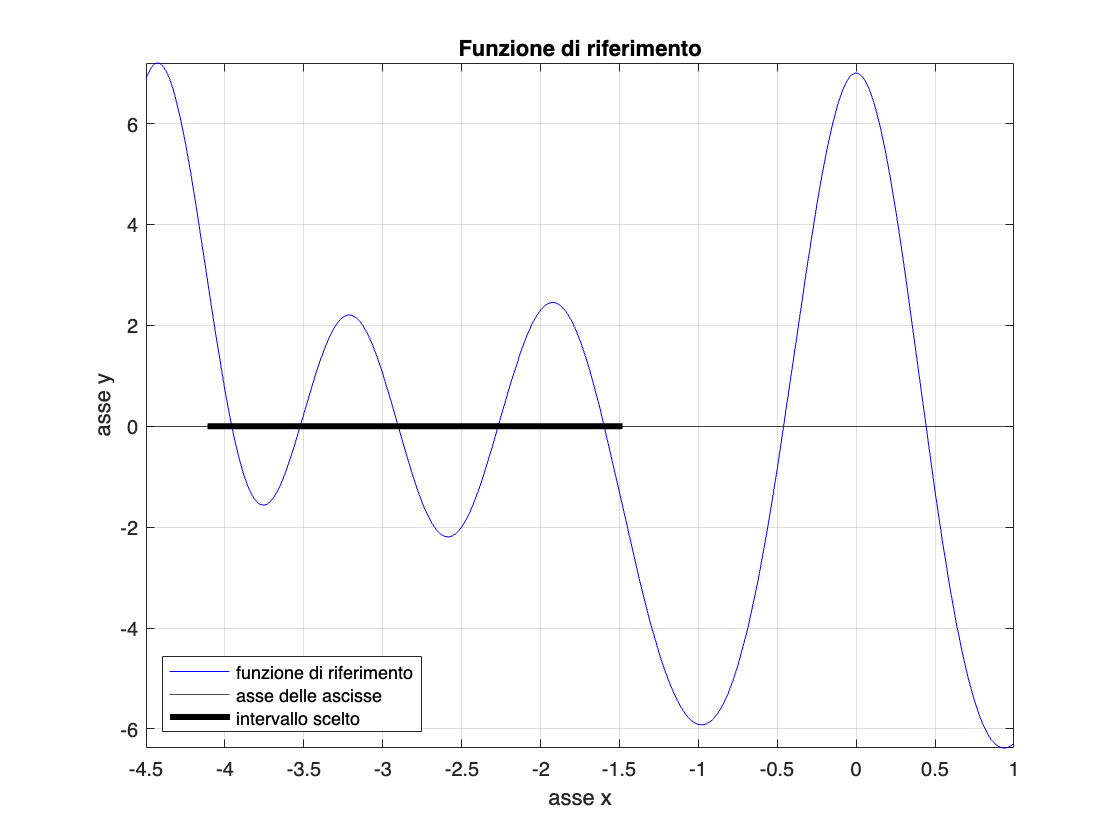

format long 

% assegno un nome alla figura
figure(1)

% scelgo un intervallo ampio per la funzione per osservarla bene
fplot(funrif,[-4.5, 1], 'color', 'b')

% conservo i grafici in modo che i nuovi grafici aggiunti non eliminino i grafici precedenti.
hold on

% visualizzo la griglia
grid on

% visualizzo l'asse delle ascisse
yline(0, 'k')

% aggiungo il titolo e nomino gli assi
xlabel("asse x")
ylabel("asse y")
title("Funzione di riferimento")

% scelgo un intervallo con 5 zeri, due minimi e due massimi
a = -4.11; b = -1.48;

% disegno una linea che evidenzia l'intervallo scelto
line([a b], [0 0], 'color', 'black', 'linewidth', 3)

% visualizzo una legenda in basso a sinistra per semplificare la lettura del grafico
legend('funzione di riferimento', 'asse delle ascisse', 'intervallo scelto', 'Location', 'southwest')

hold off

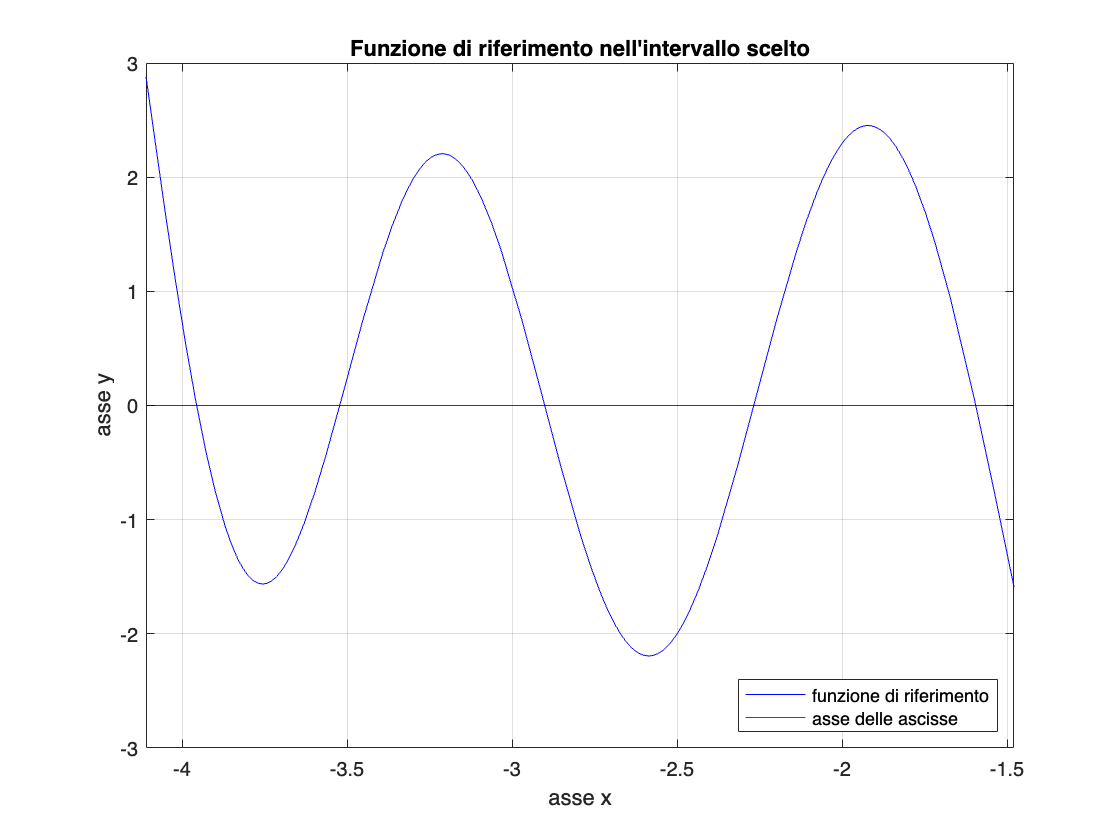

figure(2)

% visualizzo un nuovo grafico rappresentante l'intervallo scelto (a = -4.11, b = -1.48)
fplot(funrif, [a b], 'Color', 'b')

% conservo i grafici in modo che i nuovi grafici aggiunti non eliminino i grafici precedenti.
hold on

% visualizzo la griglia
grid on

% visualizzo l'asse delle ascisse
yline(0, 'k')

% aggiungo il titolo e nomino gli assi
xlabel("asse x")
ylabel("asse y")
title("Funzione di riferimento nell'intervallo scelto")

% visualizzo una legenda in basso a destra per semplificare la lettura del grafico
legend('funzione di riferimento', 'asse delle ascisse', 'Location', 'southeast')

% miglioro la visualizzazione del grafico estendendo
axis([a b -3 3])

hold off

### **PUNTO 3:**

**usate la function Matlab **`fzero`** per determinare i 5 zeri della vostra funzione di riferimento in **$[a,b]$**, e considerate i valori calcolati da **`fzero`** come le soluzioni esatte.**

Visualizzo un nuovo grafico rappresentante l'intervallo scelto (a = -4.11, b = -1.48)

figure(3)
fplot(funrif, [a b], 'Color', 'b')

% conservo i grafici in modo che i nuovi grafici aggiunti non eliminino i grafici precedenti.
hold on

% visualizzo la griglia
grid on

% visualizzo l'asse delle ascisse
yline(0, 'k')

% definisco un array contenente le approssimazioni dei 5 zeri richiesti
apprZero = [-3.95 -3.5 -2.9 -2.2 -1.6];


Definisco un array di dimensione pari all'array delle approssimazioni, in cui ogni elemento è inizializzato a zero:

zeroEsatto = zeros(size(apprZero));

Eseguo un ciclo for sui 5 elementi dell'array `zeroEsatto` per calcolarmi, con `fzero`, gli zeri esatti della funzione di riferimento.

La funzione `fzero` utilizza un metodo ibrido, cioè prende caratteristiche di più metodi, converge sempre. Prende in input la funzione di riferimento e l'approssimazone iniziale della soluzione.

La `fzero` non calcola tutti i zeri di una funzione, ma uno alla volta; per questo motivo, la inseriamo in un ciclo `for`.

for i = 1:5
    zeroEsatto(i) = fzero(funrif, apprZero(i));
end

% visualizzo i valori dei 5 zeri esatti calcolati
zeroEsatto

zeroEsatto =   -3.956646856777575  -3.522879254363641  -2.901949018617540  -2.268450586148935  -1.595710728765910


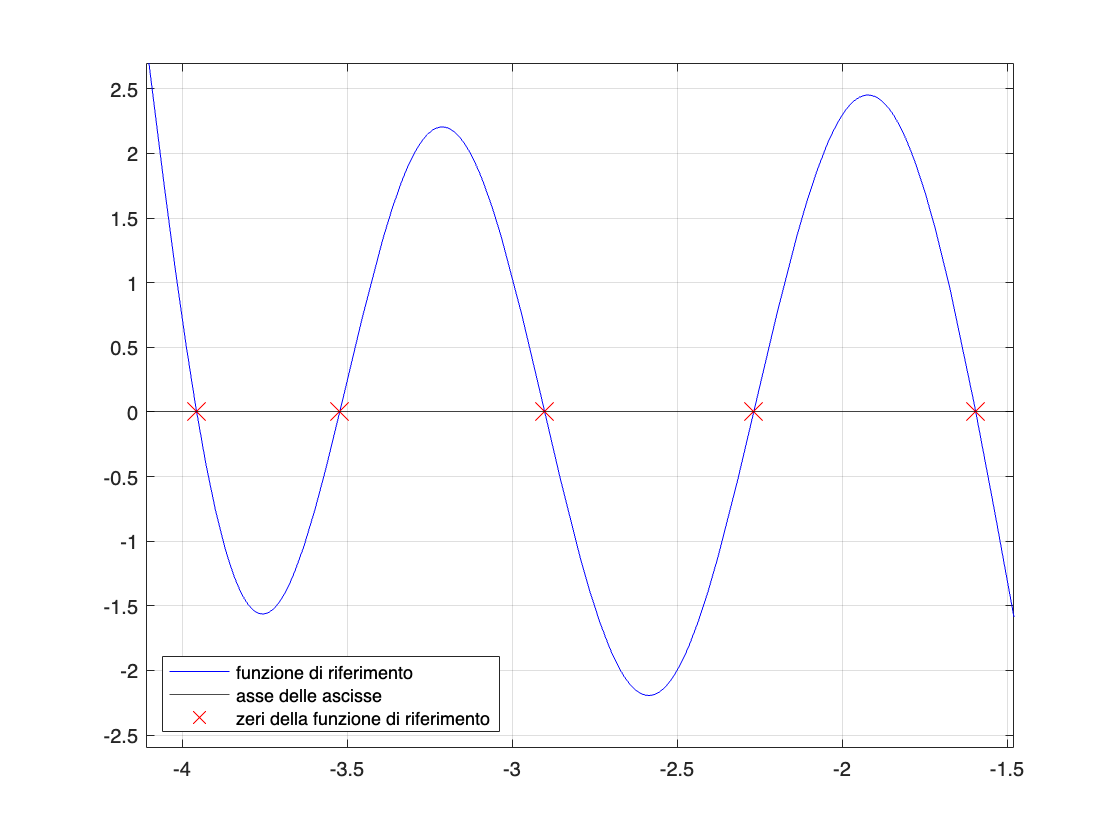

% evidenzio sul grafico della funzione di riferimento gli zeri della funzione
plot(zeroEsatto, [zeros(size(zeroEsatto))], 'x', 'color', 'r', 'MarkerSize', 13)

% miglioro la visualizzazione del grafico estendendo
axis([a b -2.6 2.7])

% visualizzo una legenda in basso a destra per semplificare la lettura del grafico
legend('funzione di riferimento', 'asse delle ascisse', 'zeri della funzione di riferimento', 'Location', 'southwest')

hold off

### **PUNTO 4:**

**indicate sul grafico (comando **`text`**) con un pallino rosso i 5 zeri, il primo valore minimo e l'ascissa del primo minimo (detta *****punto di minimo 1*****) entrambi con un triangolino down blu, il secondo valore minimo e l'ascissa del secondo minimo (detta *****punto di minimo 2*****) entrambi con un triangolino down verde, il primo valore massimo e l'ascissa del primo massimo (detta *****punto di massimo 1*****) entrambi con un triangolino up blu, il secondo valore massimo e l'ascissa del secondo massimo (detta *****punto di massimo 2*****) entrambi con un triangolino up verde; usate i comandi **`title`** e **`legend`** per rendere più leggibile la figura.**

figure(4)

% visualizzo la nostra funzione di riferimento nell'intervallo scelto (a = -4.11, b = -1.48)
fplot(funrif,[a, b],'color','b')

% conservo i grafici in modo che i nuovi grafici aggiunti non eliminino i grafici precedenti.
hold on

% visualizzo la griglia
grid on

% aggiungo il titolo e nomino gli assi
xlabel("asse x")
ylabel("asse y")
title("Funzione di riferimento")

% visualizzo l'asse delle ascisse
yline(0,'k')

% disegno la funzione di riferimento evidenziando, con un pallino rosso, gli zeri esatti della funzione
plot(zeroEsatto, [zeros(size(zeroEsatto))], 'o','color','r','MarkerFaceColor','r')

% scrivo sul grafico la variabile zeroPoint, che indica gli zeri esatti della funzione
text(zeroEsatto(1)-0.27,0.3, 'ZERO 1', "Color", 'r')
text(zeroEsatto(2)+0.03,0.3, 'ZERO 2', "Color", 'r')
text(zeroEsatto(3)+0.03,0.35, 'ZERO 3', "Color", 'r')
text(zeroEsatto(4)+0.03,0.3, 'ZERO 4', "Color", 'r')
text(zeroEsatto(5)+0.03,0.3, 'ZERO 5', "Color", 'r')

% disegno un triangolo blu rivolto verso il basso che evidenzia il primo punto di minimo e la rispettiva proiezione sull'asse delle ascisse
text(-3.83, -1.9, "MIN 1", "Color", 'b')
text(-3.86, 0.35, "p.min 1", "Color", 'b')
plot([-3.76469 -3.76469], [-1.56055 0], 'v','color','b','MarkerFaceColor','b')

% disegno un triangolo blu rivolto verso l'alto che evidenzia il primo punto di massimo e la rispettiva proiezione sull'asse delle ascisse
text(-3.29, 2.6, "MAX 1", "Color", 'b')
text(-3.3, -0.2, "p.max 1", "Color", 'b')
plot([-3.21276 -3.21276], [2.20466 0], '^','color','b','MarkerFaceColor','b')

% disegno un triangolo verde rivolto verso il basso che evidenzia il secondo punto di minimo e la rispettiva proiezione sull'asse delle ascisse
text(-2.7, -2.55, "MIN 2", "Color", 'g')
text(-2.65, -0.4, "p.min 2", "Color", 'g')
plot([-2.58461 -2.58461], [-2.19325 0], 'v','color','g','MarkerFaceColor','g')

% disegno un triangolo verde rivolto verso l'alto che evidenzia il secondo punto di massimo e la rispettiva proiezione sull'asse delle ascisse
text(-2.02, 2.85, "MAX 2", "Color", 'g')
text(-2.06, -0.4, "p.max 2", "Color", 'g')
plot([-1.92971 -1.92971], [2.45068 0], '^','color','g','MarkerFaceColor','g')


Visualizzo una legenda in basso a sinistra per semplificare la lettura del grafico.

Definisco delle variabili per le labels in modo da non rendere la legend molto lunga.

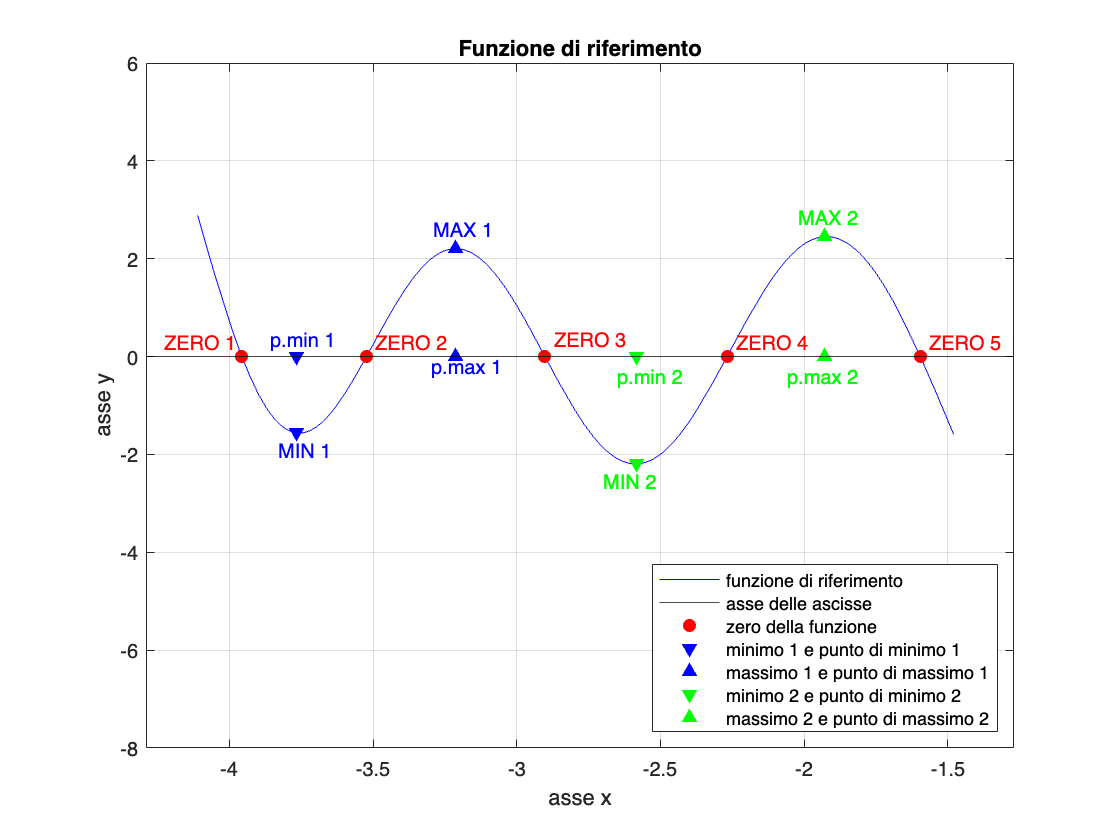

funrifLabel = 'funzione di riferimento';
axisLabel = 'asse delle ascisse';
zeroLabel = 'zero della funzione';
min1 = 'minimo 1 e punto di minimo 1';
max1 = 'massimo 1 e punto di massimo 1';
min2 = 'minimo 2 e punto di minimo 2';
max2 = 'massimo 2 e punto di massimo 2';
legend(funrifLabel, axisLabel, zeroLabel, min1, max1, min2, max2, 'Location', 'southeast')

% miglioro la visualizzazione del grafico estendendo l'asse delle ordinate
axis([-4.29 -1.27 -8 6])

hold off

### **PUNTO 5:**

**determinate un'approssimazione dei 5 zeri, usando il metodo di bisezione (nostra function **`bisezione`**) per lo zero più piccolo e per il secondo zero, il metodo delle Secanti (nostra function **`Secanti`**) per il terzo zero  e il metodo di Newton (nostra function **`Newton`**) per il quarto e il quinto zero (consiglio: usare **`funtool`** oppure il toolbox simbolico (comando **`diff`**) per determinare l'espressione della derivata della funzione di riferimento), con un valore di **`delta_ass`** che garantisca, in tutti e 5 i casi, che la parte intera e le prime 8 cifre frazionarie siano corrette.**

#### *Metodo di bisezione*

Il ***metodo di bisezione*** è un algoritmo iterativo globale e a velocità di convergenza lineare che risolve il problema f(x) = 0; è utilizzabile se f è una funzione continua e se si conosce un intervallo che contiene la soluzione, ai cui estremi la f assume valori di segno opposto. 

Con ***globale*** si intende che l’algoritmo è sempre convergente, quando è applicabile.

Con ***velocità di convergenza lineare*** si intende che l’errore si riduce di un fattore costante a ogni passo di iterazione.

L’algoritmo è basato sull’approccio detto *divide et impera*, che riduce progressivamente (dimezzandolo a ogni passo) l’intervallo che contiene la soluzione.

Definisco la stima del massimo errore assoluto richiesto sul risultato (nel nostro caso $10^{-8}$):

delta_ass = 1e-8;

Calcolo l'approssimazione del primo zero più piccolo e del secondo zero più piccolo usando il metodo di bisezione.

Tale metodo ha come parametri:

- il primo parametro di input deve essere l'handle alla function che implementa la funzione `funrif`.

- il secondo e il terzo sono gli estremi dell'intervallo iniziale.

- l'ultimo parametro è l’accuratezza che si vuole sul risultato da calcolare primo zero più piccolo

% primo zero più piccolo
zb1 = bisezione(funrif, -3.96, -3.95, delta_ass)

zb1 =   -3.956646857261658


% secondo zero
zb2 = bisezione(funrif, -3.53, -3.52, delta_ass)

zb2 =   -3.522879252433777


Per il terzo zero utilizzeremo il metodo delle Secanti.

#### *Metodo delle Secanti*

Il ***metodo delle secanti*** è un algoritmo iterativo locale e a velocità di convergenza superlineare che risolve il problema $f(x) = 0$; è utilizzabile se $f$ è una funzione continua e se si conosce una buona approssimazione iniziale della soluzione.

Con locale si intende che l’algoritmo non è sempre convergente e che la convergenza dipende da come si sceglie la condizione iniziale. Con velocità di convergenza superlineare si intende che, a ogni passo di iterazione, l’errore relativo si riduce diventando una potenza dell’errore precedente L’algoritmo è basato sull’idea di approssimare linearmente la f, a ogni passo p di iterazione, con la retta che passa per i due punti (xp, f(xp)) e (xp-1, f(xp-1)), il cui coefficiente angolare è (f(xp) - f(xp-1)) /(xp - xp-1), e di considerare lo zero di tale retta come approssimazione dello zero di f.

Tale metodo ha come parametri:

- il primo parametro di input deve essere l'handle alla function che implementa la funzione `funrif`.

- il secondo e il terzo sono gli estremi dell'intervallo iniziale.

- il quarto parametro è l’accuratezza che si vuole sul risultato da calcolare primo zero più piccolo.

- l'ultimo parametro è il numero massimo di iterazioni consentite.

% definisco il numero massimo di iterazioni
kmax = 10;

% terzo zero
zsec = Secanti(funrif, -3, -2.9, delta_ass, kmax)

zsec =   -2.901949018609956


Per gli ultimi due zeri utilizzeremo il metodo di Newton.

#### *Metodo di Newton*

Il ***metodo di Newton*** è un algoritmo iterativo locale e a velocità di convergenza quadratica che risolve il problema f(x) = 0; è utilizzabile se f è una funzione continua e derivabile (con derivata nota) e se si conosce una buona approssimazione iniziale della soluzione.

Con locale si intende che l’algoritmo non è sempre convergente e che la convergenza dipende da come si sceglie la condizione iniziale. Con velocità di convergenza quadratica si intende che, a ogni passo di iterazione, l’errore relativo si riduce diventando il quadrato dell’errore precedente.

L’algoritmo è basato sull’idea di approssimare linearmente la f, a ogni passo p di iterazione, con la retta tangente alla f nel punto (xp, f(xp)), il cui coefficiente angolare1 è f’(xp), e di considerare lo zero di tale retta come approssimazione dello zero di f.

La derivata prima di funrif calcolata con `funtool`:


$$$$ 5\cdot\cos\left(\frac{5x}{2}\right)\cdot\sin\left(\frac{5x}{2}\right)\cdot e^{-0.5\cdot x} - 0.5\cdot\sin\left(\frac{5x}{2}\right)^2\cdot e^{-0.5\cdot x} - \frac{9\pi\cdot\sin(\pi x)}{x^2+1} - \frac{18x\cdot\cos(\pi x)}{(x^2+1)^2} $$$$


% definisco in una variabile la derivata prima
derfunrif = @(x) 5*cos((5*x)/2).*sin((5*x)/2).*exp(-0.5*x) - 0.5*sin((5*x)/2).^2.*exp(-0.5*x) - (9*pi*sin(x*pi))./(x.^2 + 1) - (18*x.*cos(x*pi))./(x.^2 + 1).^2;

Richiamiamo la funzione `Newton` che ha come parametri:

- il primo parametro è un puntatore alla function che definisce la funzione di cui si vuole calcolare lo zero.

- il secondo parametro è una function che definisce $f^{\prime }$.

- il terzo parametro è la prima approssimazione della successione delle approssimazioni.

- il quarto parametro, `delta_ass`, è il massimo errore consentito sull'approssimazione.

- l'ultimo parametro corrisponde al numero massimo di iterazioni consentite; quest'ultimo parametro lo indichiamo dato che il metodo di Newton non converge sempre.

% calcolo il quarto zero con il metodo di Newton
zeronew1 = Newton(funrif, derfunrif, -2.4, delta_ass, kmax)

zeronew1 =   -2.268450586023778


% calcolo il quinto zero con il metodo di Newton
zeronew2 = Newton(funrif, derfunrif, -1.7, delta_ass, kmax)

zeronew2 =   -1.595710728765909


### **Punto 6:**

**considerate sia l'errore assoluto tra l'approssimazione della bisezione e la corrispondente soluzione esatta (per entrambi gli zeri calcolati con **`bisezione`**), sia l'errore assoluto tra l'approssimazione delle Secanti e la corrispondente soluzione esatta, sia l'errore assoluto tra l'approssimazione di Newton e la corrispondente soluzione esatta (per entrambi gli zeri calcolati con **`Newton`**) e verificate che siano minori dell'accuratezza richiesta (**`delta_ass`**), commentando il loro valore; calcolate anche il residuo per ognuna delle cinque approssimazioni e commentate i valori del residuo confrontandoli con quelli del corrispondente errore assoluto  e con l'accuratezza richiesta; guardando il grafico della funzione di riferimento dire se, per ognuno dei cinque zeri, il problema appare bene o mal condizionato e poi calcolare l'indice di condizionamento per ognuno dei cinque zeri.**

Consideriamo un numero $x$ ed una sua approssimazione $a$. L'***errore assoluto*** è in genere definito come la *differenza tra il valore misurato e il valore esatto di una misura*. Se l'errore assoluto è minore di ${10}^{-m\;}$, dove $m$ è l'esponente che appare nell'errore assoluto, possiamo dire che $x$ ed $a$ hanno la stessa parte intera e le prime $m$ cifre della parte frazionaria. 

Calcoliamo l'errore assoluto con il primo zero esatto ottenuti col metodo di bisezione:

errAssBis1 = abs(zb1 - zeroEsatto(1))

errAssBis1 =      4.840834399999494e-10


Il valore dell'errore assoluto è più piccolo del `delta_ass`; per un'ulteriore conferma, controllo se l'errore assoluto appena ottenuto è minore di `delta_ass`:

if (errAssBis1 < delta_ass)
    disp('Disequazione verificata')
else
    disp('Disequazione non verificata')
end

Disequazione verificata


Come si può notare, il risultato di questo confronto è un `logical 1`, ovvero la disequazione $\textrm{errAssBis1}<\textrm{delta}\_\textrm{ass}$ è verificata.

Analogamente, controlliamo l'errore sul secondo valore dello zero esatto ottenuto precedentemente col metodo di bisezione:

errAssBis2 = abs(zb2 - zeroEsatto(2))

errAssBis2 =      1.929864268390702e-09


Il valore dell'errore assoluto è più piccolo del `delta_ass`; per un'ulteriore conferma, controllo se l'errore assoluto appena ottenuto è minore di `delta_ass`:

if (errAssBis2 < delta_ass)
    disp('Disequazione verificata')
else
    disp('Disequazione non verificata')
end

Disequazione verificata


Come si può notare, il risultato di questo confronto è un `logical 1`, ovvero la disequazione $\textrm{errAssBis2}<\textrm{delta}\_\textrm{ass}$ è verificata.

Eseguiamo ora lo stesso procedimento andando a calcolare l'errore assoluto con lo zero ottenuto dal metodo delle secanti:

errAssSec = abs(zsec - zeroEsatto(3))

errAssSec =      7.584155525819369e-12


Il valore dell'errore assoluto è più piccolo del `delta_ass`; per un'ulteriore conferma, controllo se l'errore assoluto appena ottenuto è minore di `delta_ass`:

if (errAssSec < delta_ass)
    disp('Disequazione verificata')
else
    disp('Disequazione non verificata')
end

Disequazione verificata


Come si può notare, il risultato di questo confronto è un `logical 1`, ovvero la disequazione $\textrm{errAssSec}<\textrm{delta}\_\textrm{ass}$ è verificata.

Calcoliamo ora l'errore assoluto col quarto zero esatto, ottenuto applicando il metodo di Newton:

errAssNew1 = abs(zeronew1 - zeroEsatto(4))

errAssNew1 =      1.251572179228333e-10


Il valore dell'errore assoluto è più piccolo del `delta_ass`; per un'ulteriore conferma, controllo se l'errore assoluto appena ottenuto è minore di `delta_ass`:

if (errAssNew1 < delta_ass)
    disp('Disequazione verificata')
else
    disp('Disequazione non verificata')
end

Disequazione verificata


Come si può notare, il risultato di questo confronto è un `logical 1`, ovvero la disequazione $\textrm{errAssNew1}<\textrm{delta}\_\textrm{ass}$ è verificata.

Calcoliamo ora l'errore assoluto col quinto zero esatto, ottenuto applicando il metodo di Newton:

errAssNew2 = abs(zeronew2 - zeroEsatto(5))

errAssNew2 =      2.220446049250313e-16


Il valore dell'errore assoluto è più piccolo del `delta_ass`; per un'ulteriore conferma, controllo se l'errore assoluto appena ottenuto è minore di `delta_ass`:

if (errAssNew2 < delta_ass)
    disp('Disequazione verificata')
else
    disp('Disequazione non verificata')
end

Disequazione verificata


Come si può notare, il risultato di questo confronto è un `logical 1`, ovvero la disequazione $\textrm{errAssNew2}<\textrm{delta}\_\textrm{ass}$ è verificata.

Andiamo ora a calcolare i residui.

Calcoliamo i residui dei due zeri ottenuti dal metodo di bisezione:

% primo residuo del primo zero
residuo_zb1 = abs(funrif(zb1))

residuo_zb1 =      7.376748989429416e-09


L'ordine di grandezza del residuo dell'approssimazione del metodo di bisezione è più piccolo dell'ordine di grandezza dell'accuratezza richiesta ${10}^{-8}$, ciò indica che il problema è *ben condizionato*.

% secondo reisduo del secondo zero
residuo_zb2 = abs(funrif(zb2))

residuo_zb2 =      2.062360371368754e-08


L'ordine di grandezza del residuo dell'approssimazione del metodo di bisezione è uguale all'ordine di grandezza dell'accuratezza richiesta ${10}^{-8}$, ciò indica che il problema è *ben condizionato*.

Calcoliamo ora il residuo dello zero ottenuto dal metodo delle secanti:

% residuo dello zero del metodo delle secanti
residuo_zsec = abs(funrif(zsec))

residuo_zsec =      8.374523297050018e-11


L'ordine di grandezza del residuo dell'approssimazione del metodo delle secanti è più piccolo dell'ordine di grandezza dell'accuratezza richiesta ${10}^{-8}$, ciò indica che il problema è *ben condizionato*.

Calcoliamo, infine, i residui degli zeri ottenuti dal metodo di Newton:

% primo residuo del primo zero del metodo di Newton
residuo_zeronew1 = abs(funrif(zeronew1))

residuo_zeronew1 =      1.370635605013604e-09


L'ordine di grandezza del residuo dell'approssimazione del metodo di newton è più piccolo dell'ordine di grandezza dell'accuratezza richiesta ${10}^{-8}$, ciò indica che il problema è *ben condizionato*.

% secondo residuo del secondo zero del metodo di Newton
residuo_zeronew2 = abs(funrif(zeronew2))

residuo_zeronew2 =      2.886579864025407e-15


L'ordine di grandezza del residuo dell'approssimazione del metodo di newton è più piccolo dell'ordine di grandezza dell'accuratezza richiesta ${10}^{-8}$, ciò indica che il problema è *ben condizionato*.

Gli ***indici di condizionamento*** possono essere utilizzati per valutare la stabilità e l'accuratezza della soluzione di un problema e per identificare eventuali problemi di mal condizionamento.

Calcoliamo tali indici per ogni metodo utilizzato:

% metodo di bisezione
kFBis1 = 1/abs(derfunrif(zeroEsatto(1)))

kFBis1 =    0.065622823180503


kFBis2 = 1/abs(derfunrif(zeroEsatto(2)))

kFBis2 =    0.093575528314398


% metodo delle secanti
kFSec = 1/abs(derfunrif(zeroEsatto(3)))

kFSec =    0.090560796752764


kFNew1 = 1/abs(derfunrif(zeroEsatto(4)))

kFNew1 =    0.091313253551023


kFNew2 = 1/abs(derfunrif(zeroEsatto(5)))

kFNew2 =    0.076500152863923


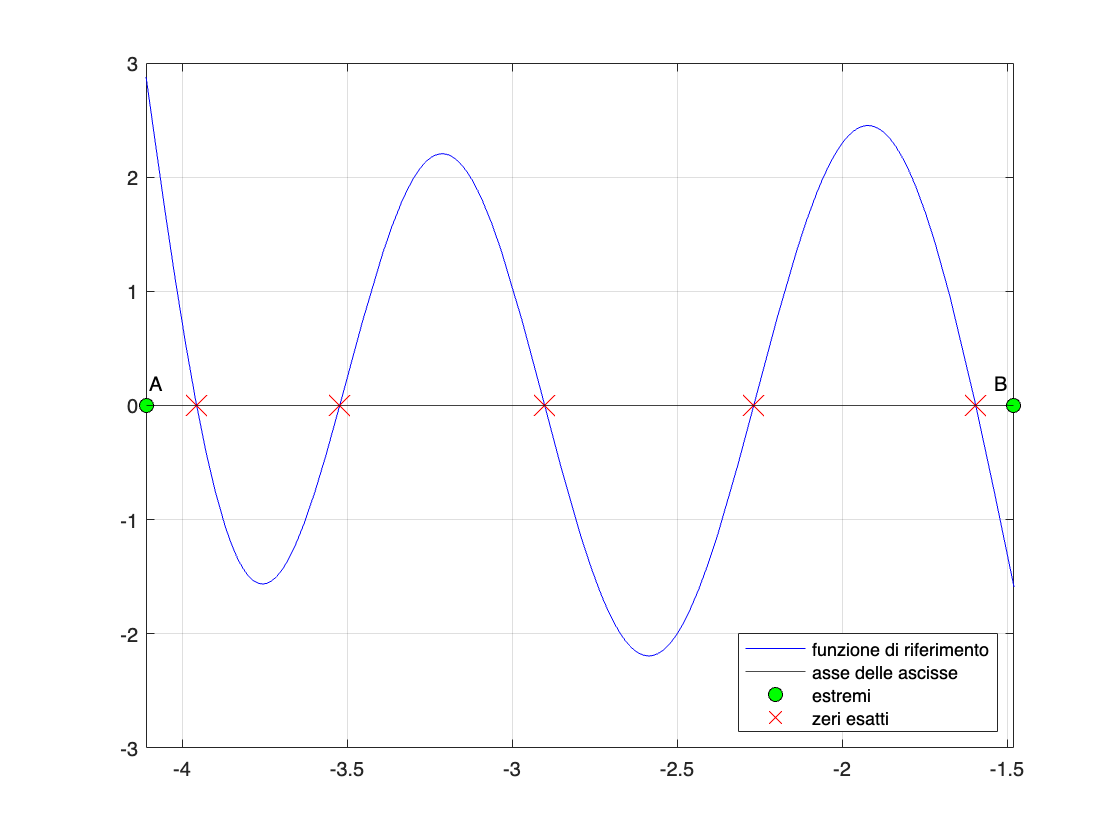

figure(5)
fplot(funrif, [a, b], 'color', 'b')

% conservo i grafici in modo che i nuovi grafici aggiunti non eliminino i grafici precedenti.
hold on

% visualizzo la griglia
grid on

% disegno l'asse delle ascisse
yline(0,'-','color','k') 

% disegno gli estremi della mia funzione
plot([a,b],[0,0],'o','markersize',7,'color','k','MarkerFaceColor','g')

% indico gli estremi della mia funzione
text(-4.1, 0.2,'A', "Color", 'k');
text(-1.54,0.2,'B', 'color','k');

% disegno gli zeri esatti sul grafico
plot([zeroEsatto(1) zeroEsatto(2) zeroEsatto(3) zeroEsatto(4) zeroEsatto(5)],[0 0 0 0 0],'x','markersize',15,'color','r')

% miglioro la visualizzazione del grafico estendendo l'asse delle ordinate
axis([a b -3 3])

% inserisco una legenda per semplificare la lettura del grafico
legend('funzione di riferimento','asse delle ascisse','estremi','zeri esatti','location', 'southeast')

hold off

Osservando il grafico si può notare che non vi sono incertezze sugli zeri calcolati, dunque il problema è ben condizionato. 

Gli indici di condizionamento precedentemente calcolati confermano tale tesi.

### Punto 7:

**osservando il grafico della vostra funzione di riferimento nell'intervallo **$[a,b]$**e della bisettrice del primo quadrante, stabilite se ci sono punti fissi e determinate il loro numero; poi, senza usare la function **`PFisso` `(`**suggerimento: usate opportunamente**` fzero)`**, calcolate una approssimazione del punto fisso più vicino all'estremo sinistro dell'intervallo, cioè più vicino ad **$a$**, visualizzatelo sul grafico con  un quadrato nero e determinate il residuo; dite se il metodo del punto fisso convergerebbe a tale punto fisso. Solo nel caso la teoria assicuri la convergenza (**`suggerimento: `**calcolate e visualizzate la derivata della funzione nel punto fisso), calcolate tale punto fisso anche con la function **`PFisso`**; commentate i risultati; usate i comandi **`title`** e **`legend`** per rendere più leggibile la figura.**

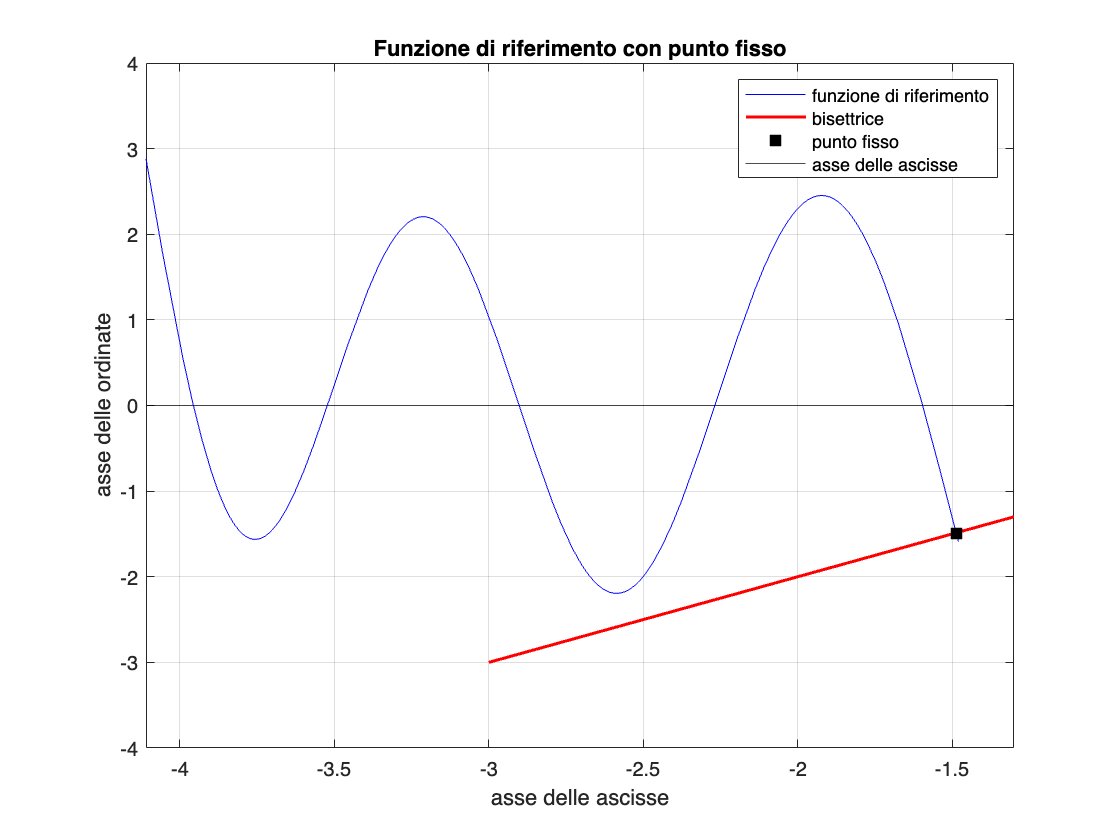

figure(6)

fplot(funrif, [a b], 'Color', 'b')

% conservo i grafici in modo che i nuovi grafici aggiunti non eliminino i grafici precedenti.
hold on

% visualizzo la griglia
grid on

% disegno la bisettrice
fplot(@(x) x, [-3 -1], 'Color', 'r', 'LineWidth', 1.5)

% evidenzio il punto fisso
plot(-1.485, -1.49, 'square', 'color', 'k', 'MarkerFaceColor', 'k', 'LineWidth', 1.5)

% disegno l'asse delle ascisse
yline(0, '-', 'Color', 'k')

% miglioro la visualizzazione del grafico estendendo l'asse delle ordinate
axis([a -1.3 -4 4])

% aggiungo il titolo e nomino gli assi
xlabel("asse delle ascisse")
ylabel("asse delle ordinate")
title("Funzione di riferimento con punto fisso")

% inserisco una legenda per semplificare la lettura del grafico
legend('funzione di riferimento', 'bisettrice', 'punto fisso', 'asse delle ascisse')

hold off

Andiamo a calcolare ora il punto fisso che, nel caso attuale, è vicino all'estremo destro dell'intervallo considerato:

puntoFisso = fzero(@(x) funrif(x) - x, -1.49)

puntoFisso =   -1.487241762227268


Adesso, andiamo a calcolare il residuo del punto fisso:

residuoPF = abs(funrif(puntoFisso) - puntoFisso)

residuoPF =      1.998401444325282e-15


Il problema del punto fisso è ben condizionato, infatti abbiamo trovato una buona approssimazione del nostro punto fisso con altissima accuratezza.

Ora, verifichiamo la convergenza:

abs(derfunrif(puntoFisso))

ans =   14.019015393006439


Il risultato è maggiore di 1, quindi il metodo del punto fisso **non **convergerebbe nel `puntoFisso`.

### Punto 8:

**usate la function Matlab **`fminbnd`** per determinare i due punti di minimo e i due punti di massimo della vostra funzione di riferimento in **$[a,b]$**, con quattro chiamate del tipo: **`fminbnd(fun,sinistro,destro,optimset('TolX',1e-10))`**, e considerate i valori calcolati da **`fminbnd`** come le soluzioni esatte (cioè come valori esatti dei due punti di minimo e dei due punti di massimo).**

La function `fminbnd `permette di trovare i punti di minimo di una funzione. Come parametri troviamo:

- l'handle della funzione.

- l'estremo sinistro e destro di un intervallo contenente la soluzione.

pMin1 = fminbnd(funrif, -3.76, -3.74, optimset('TolX', 1e-10))

pMin1 =   -3.756633957184383


min1 = funrif(pMin1)

min1 =   -1.562998510230491


pMin2 = fminbnd(funrif, -2.6, -2.5, optimset('TolX', 1e-10))

pMin2 =   -2.586652773700344


min2 = funrif(pMin2)

min2 =   -2.193359301180897


Andiamo ora a calcolare i punti di massimo. Per fare ciò, bisogna passare alla `fminbnd` la funzione opposta della funzione di riferimento; quindi:

revfunrif = @(x) -funrif(x);

`revfunrif` è la funzione inversa della funzione di riferimento. Andiamo ora a calcolare i massimi:

pMax1 = fminbnd(revfunrif, -3.28, -3.1, optimset('TolX', 1e-10))

pMax1 =   -3.212318750384882


max1 = funrif(pMax1)

max1 =    2.204740205797602


pMax2 = fminbnd(revfunrif, -1.98, -1.8, optimset('TolX', 1e-10))

pMax2 =   -1.922587843675517


max2 = funrif(pMax2)

max2 =    2.451990522099365


Andiamo a disegnare ora il grafico andando ad evidenziare punti di massimo, minimo, minimi e massimi.

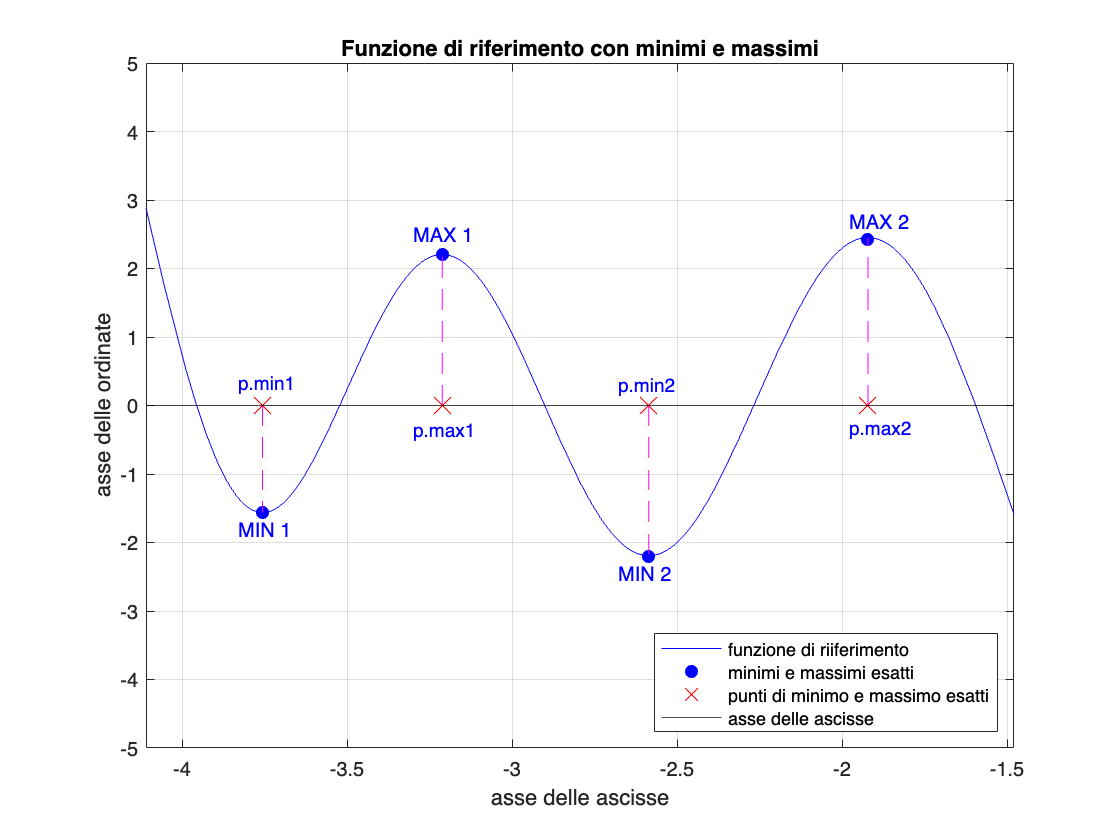

figure(7)

% disegno la mia funzione di riferimento nell'intervallo [a, b]
fplot(funrif, [a, b], 'color', 'b')

% conservo i grafici in modo che i nuovi grafici aggiunti non eliminino i grafici precedenti.
hold on

% visualizzo la griglia
grid on

% aggiungo il titolo e nomino gli assi
xlabel("asse delle ascisse")
ylabel("asse delle ordinate")
title("Funzione di riferimento con minimi e massimi")

% disegno l'asse delle ascisse
yline(0, '-', 'color', 'k')

% indico i massimi e minimi sulla mia funzione
text(-3.83,-1.8, "MIN 1","Color",'b')
text(-2.68,-2.45, "MIN 2","Color",'b')
text(-3.3,2.5,"MAX 1","Color",'b')
text(-1.98,2.69,"MAX 2","Color",'b')

% disegno i minimi e massimi
plot([pMin1 pMin2 pMax1 pMax2], [-1.56 -2.2 2.2 2.43], 'o','color','b','MarkerFaceColor','b')

% disegno i minimi e massimi sull'asse delle ascisse
plot([pMin1 pMin2 pMax1 pMax2], [0 0 0 0], 'x','color','r','MarkerFaceColor','b', 'MarkerSize', 12)

% indico i punti di minimo e di massimo sull'asse delle ascisse
text(-3.83,0.35,'p.min1', "Color", 'b',"FontSize",9.5);
text(-2.68,0.32,'p.min2', "Color", 'b',"FontSize",9.5);
text(-3.3,-0.35,'p.max1', "Color", 'b',"FontSize",9.5);
text(-1.98,-0.32,'p.max2', "Color", 'b',"FontSize",9.5);

% disegno le proiezioni dei massimi e minimi sull'asse delle ascisse
plot([pMin1,pMin1], [0,min1], '--','color','m')
plot([pMin2,pMin2], [0,min2], '--','color','m')
plot([pMax1,pMax1], [0,max1], '--','color','m')
plot([pMax2,pMax2], [0,max2], '--','color','m')

% miglioro la visualizzazione del grafico estendendo l'asse delle ordinate
axis([a b -5 5])

% inserisco una legeda per semplificare la lettura del grafico
legend('funzione di riiferimento','asse delle ascisse','minimi e massimi esatti','punti di minimo e massimo esatti', 'location', 'southeast')


hold off

### Punto 9:

**verificate che i due punti di minimo e i due punti di massimo sono zeri della derivata della vostra funzione di riferimento (consiglio: usare **`funtool`** o il toolbox simbolico (comando **`diff`**) per determinare l'espressione della derivata della funzione di riferimento), visualizzando nella stessa figura sia il grafico della funzione (in blu) sia il grafico della sua derivata (in rosso) [può essere utile usare anche la scalatura della finestra grafica data dal comando **`axis([xmin xmax ymin ymax])`** ], e usando la **`fzero`** per calcolare tutti gli zeri della derivata; commentate i risultati ottenuti; usate i comandi **`title`** e **`legend`** per rendere più leggibile la figura.**

Sappiamo che se una funzione ammette massimo o minimo in un punto, la derivata prima in quel punto, qualora dovesse esistere, è *uguale a 0*.

Calcoliamo quindi gli zeri della derivata prima, i quali dovrebbero coincidere con i punti di minimo e massimo della funzione:

zero_dev1 = fzero(derfunrif, -3.8)

zero_dev1 =   -3.756633966174236


zero_dev2 = fzero(derfunrif, -2.7)

zero_dev2 =   -2.586652773648143


zero_dev3 = fzero(derfunrif, -3.3)

zero_dev3 =   -3.212318749621628


zero_dev4 = fzero(derfunrif, -2)

zero_dev4 =   -1.922587835902238


Come è possibile notare, i risultati si discostano dai punti di minimo e massimo solo per quanto riguarda le ultime cifre frazionarie, nonostante ciò possiamo concludere che i risultati siano ugualemente coincidenti come ci si aspettava.

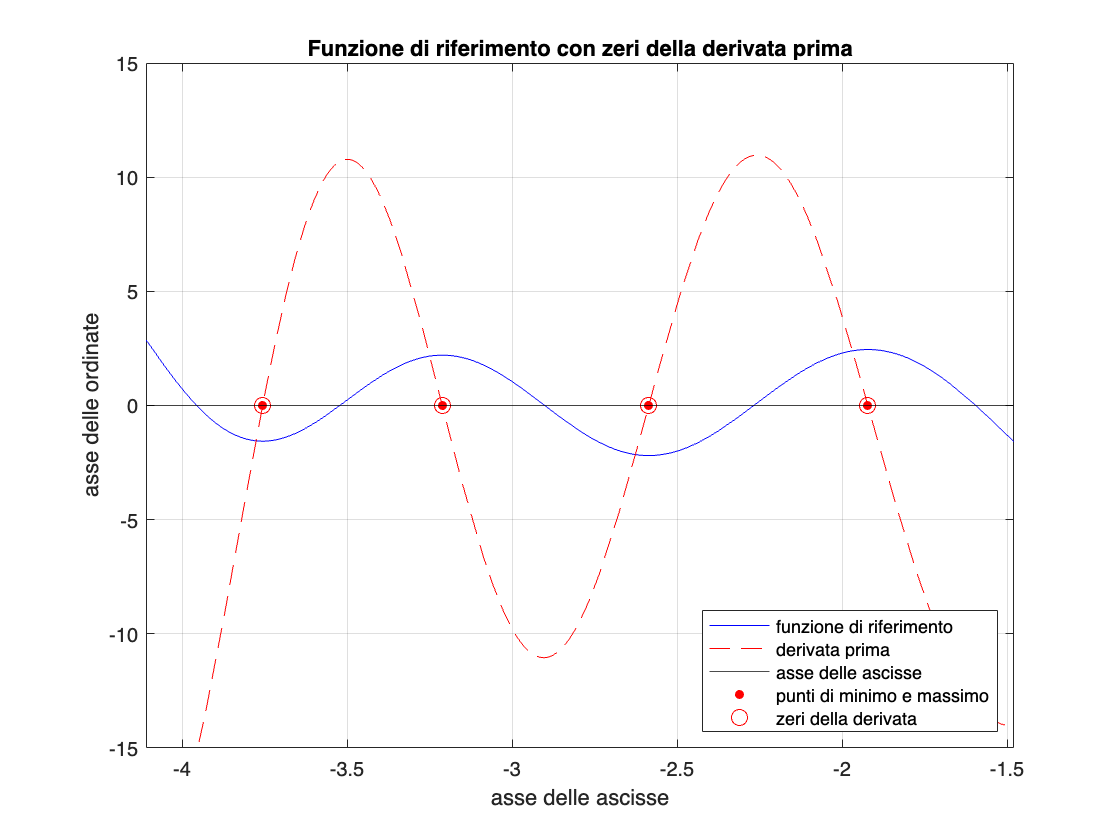

figure(8)

% disegno la mia funzione di riferimento nell'intervallo [a, b]
fplot(funrif, [a, b], 'color', 'b')

% conservo i grafici in modo che i nuovi grafici aggiunti non eliminino i grafici precedenti.
hold on

% visualizzo la griglia
grid on

% disegno la derivata prima della mia funzione di riferimento
fplot(derfunrif, [a b], '--', 'Color', 'r')

% disegno l'asse delle ascisse
yline(0, '-', 'Color', 'k')

% evidenzio i punti di minimo e di massimo sull'asse delle ascisse
plot([pMin1 pMin2 pMax1 pMax2], [0 0 0 0], 'or', 'MarkerFaceColor', 'r', 'MarkerSize', 4)

% evidenzio gli zeri della derivata prima
plot([zero_dev1 zero_dev2 zero_dev3 zero_dev4], [0 0 0 0], 'o', 'Color', 'r', 'MarkerSize', 8)

% aggiungo il titolo e nomino gli assi
xlabel("asse delle ascisse")
ylabel("asse delle ordinate")
title("Funzione di riferimento con zeri della derivata prima")

% inserisco una legeda per semplificare la lettura del grafico
legend('funzione di riferimento', 'derivata prima', 'asse delle ascisse', 'punti di minimo e massimo', 'zeri della derivata', 'Location','southeast')

% miglioro la visualizzazione del grafico estendendo l'asse delle ordinate
axis([a b -15 15])

hold off

### Punto 10:

**Determinate un'approssimazione dei due punti di minimo e dei due punti di massimo, usando, rispettivamente, due volte il metodo di Fibonacci search (nostra function **`fminfibo`**) per i due massimi, e il metodo di Golden search (nostra function **`fmingolden`**) per i due minimi, con un valore di **`delta_ass`** che garantisca che la parte intera e le prime 4 cifre frazionarie siano corrette.**

#### ***Metodo di ricerca di Fibonacci***

Il ***metodo di ricerca di Fibonacci*** (***Fibonacci search***) è un algoritmo globale a velocità lineare. Tale metodo è utilizzabile a patto di scegliere un intervallo in cui la risulta **unimodale**, ciò significa che esiste un unico numero $r$ in $[a, b]$ tale che $f$ è decrescente in $[a, r]$ e crescente in $[r, b]$.

Tale algoritmo ha come argomenti:

- il primo argomento è l'handle alla function che definisce $f(x)$.

- il secondo argomento è l'estremo sinistro dell'intervallo.

- il terzo argomento è l'estremo destro dell'intervallo.

- il quarto argomento è l'errore massimo richiesto sul risultato.

Come errore massimo, considero `1e-4`

pmaxfibo1 = fminfibo(revfunrif, -3.25, -3.09, 1e-4)

pmaxfibo1 =   -3.212391084093212


pmaxfibo2 = fminfibo(revfunrif, -1.95, -1.9, 1e-4)

pmaxfibo2 =   -1.922532188841202


#### *Metodo di ricerca aurea (golden search)*

Il ***metodo della ricerca aurea ***(o*** Golden Search***) può essere considerato come una variante del metodo di Fibonacci. Esso si basa su risultati noti sulla successione dei numeri di Fibonacci.

Tale metodo ha come argomenti:

- l'handle alla function Matlab che definisce la funzione obiettivo.

- l'estremo sinistro dell'intervallo che racchiude la soluzione.

- l'estremo destro dell'intervallo che racchiude la soluzione.

- l'accuratezza richiesta

mingolden1 = fmingolden(funrif, -3.76, -3.74, 1e-4)

mingolden1 =   -3.756625258399798


mingolden2 = fmingolden(funrif, -2.6, -2.55, 1e-4)

mingolden2 =   -2.586677773906473


Andiamo a rappresentare ora graficamente i punti appena trovati:

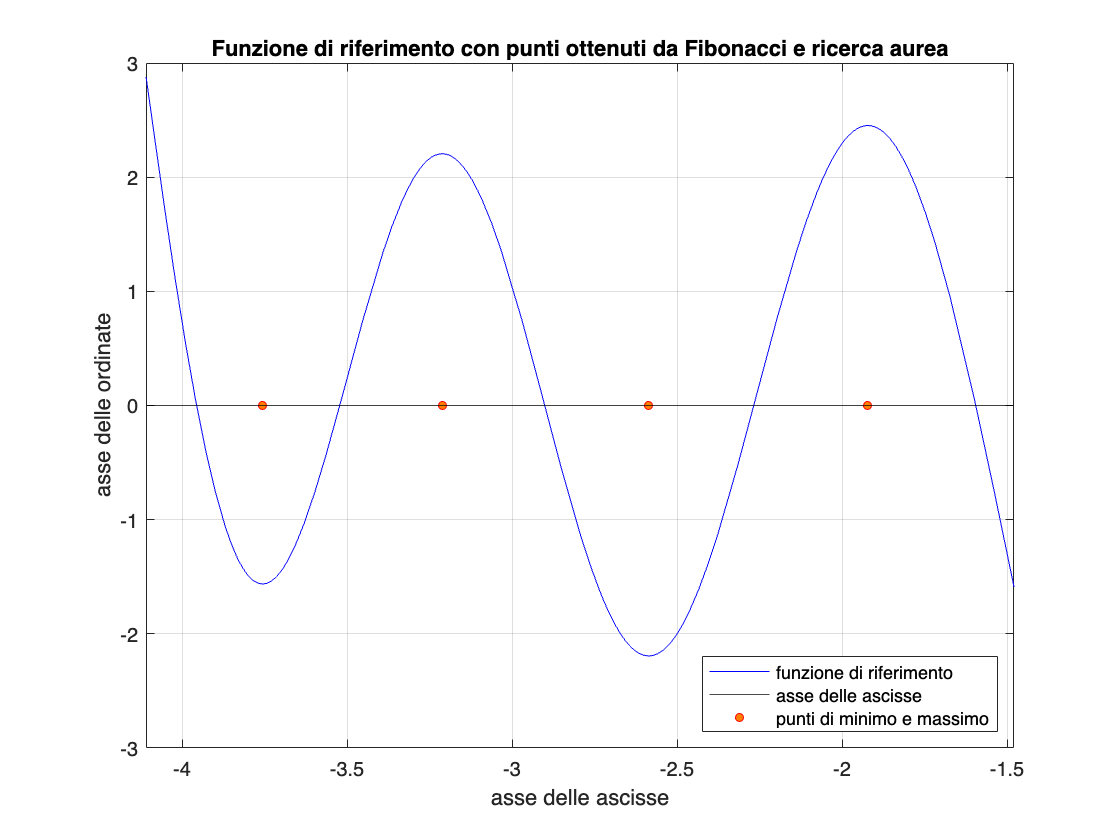

figure(9)

% disegno la mia funzione di riferimento nell'intervallo [a, b]
fplot(funrif, [a, b], 'color', 'b')

% conservo i grafici in modo che i nuovi grafici aggiunti non eliminino i grafici precedenti.
hold on

% visualizzo la griglia
grid on

% disegno l'asse delle ascisse
yline(0, '-', 'Color', 'k')

% evidenzio i punti calcolati con la ricerca di Fibonacci e la ricerca aurea
plot([mingolden1 mingolden2 pmaxfibo1 pmaxfibo2], [0 0 0 0], 'o', 'Color', 'r', 'MarkerFaceColor', '#ff8001', 'MarkerSize', 4)

% aggiungo il titolo e nomino gli assi
xlabel("asse delle ascisse")
ylabel("asse delle ordinate")
title("Funzione di riferimento con punti ottenuti da Fibonacci e ricerca aurea")

% inserisco una legeda per semplificare la lettura del grafico
legend('funzione di riferimento', 'asse delle ascisse', 'punti di minimo e massimo', 'Location','southeast')

% miglioro la visualizzazione del grafico estendendo l'asse delle ordinate
axis([a b -3 3])

hold off

### Punto 11:

**Considerate l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Golden search e le due corrispondenti soluzioni esatte e poi l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Fibonacci search e le due corrispondenti soluzioni esatte, e verificate che siano in tutti e quattro i casi minori dell'accuratezza richiesta (**`delta_ass`**), commentando i risultati.**

Andiamo a calcolare gli errori assoluti con un'accuratezza di `1e-4`:

err_ass_gold1 = abs(mingolden1 - pMin1)

err_ass_gold1 =      8.698784584648678e-06


if err_ass_gold1 < 1e-4
    disp('L''errore assoluto tra mingolden1 e pMin1 è minore dell''accuratezza richiesta.')
else
    disp('L''errore assoluto tra mingolden1 e pMin1 è maggiore o uguale dell''accuratezza richiesta.')
end

L'errore assoluto tra mingolden1 e pMin1 è minore dell'accuratezza richiesta.


err_ass_gold2 = abs(mingolden2 - pMin2)

err_ass_gold2 =      2.500020612927756e-05


if err_ass_gold2 < 1e-4
    disp('L''errore assoluto tra mingolden2 e pMin2 è minore dell''accuratezza richiesta.')
else
    disp('L''errore assoluto tra mingolden2 e pMin2 è maggiore o uguale dell''accuratezza richiesta.')
end

L'errore assoluto tra mingolden2 e pMin2 è minore dell'accuratezza richiesta.


err_ass_fibo1 = abs(pmaxfibo1 - pMax1)

err_ass_fibo1 =      7.233370832926411e-05


if err_ass_fibo1 < 1e-4
    disp('L''errore assoluto tra pmaxfibo1 e pMax1 è minore dell''accuratezza richiesta.')
else
    disp('L''errore assoluto tra pmaxfibo1 e pMax1 è maggiore o uguale dell''accuratezza richiesta.')
end

L'errore assoluto tra pmaxfibo1 e pMax1 è minore dell'accuratezza richiesta.


err_ass_fibo2 = abs(pmaxfibo2 - pMax2)

err_ass_fibo2 =      5.565483431491103e-05


if err_ass_fibo2 < 1e-4
    disp('L''errore assoluto tra pmaxfibo2 e pMax2 è minore dell''accuratezza richiesta.')
else
    disp('L''errore assoluto tra pmaxfibo2 e pMax2 è maggiore o uguale dell''accuratezza richiesta.')
end

L'errore assoluto tra pmaxfibo2 e pMax2 è minore dell'accuratezza richiesta.
